# Graphing

## What we've covered this week in Part 1

This week in Part 1 we learnt about:

- Interactively plotting data

- Interactively controlling the plot view

- Property inspector

- Interactively formatting plots

- Interactively exporting to another application

## Programmatic Plotting

We now move to using commands to plot our data, rather than doing everything through the graphical interface. MATLAB offers a large variety of built-in functions to create several standard chart types.

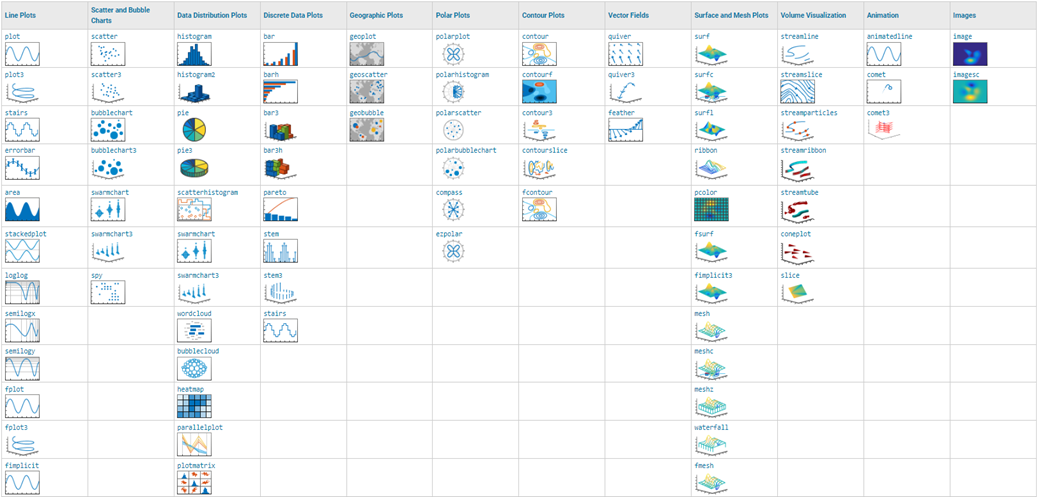

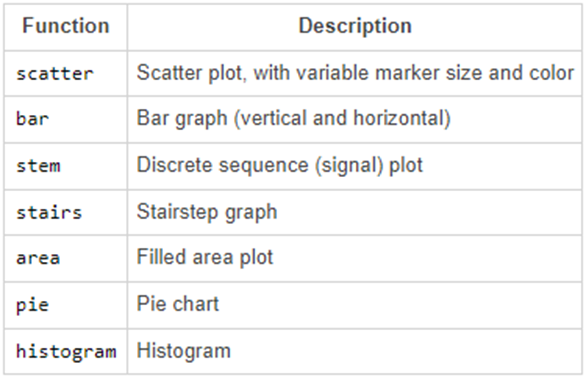

See the complete list of all available plots [here](http://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html)

Let’s see an example making use of MATLAB’s plotting function.

Previously we plotted interactively, now let’s plot the Mexico data against Year programmatically using a linear plot:

load AuDeMx.mat

plot(Year, Mexico)

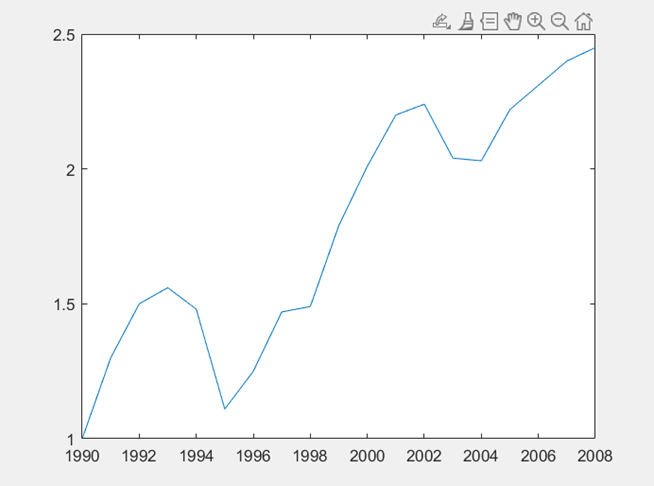

Now you try! Plot the Australia data as a function of Year:

%Plot your data here


### **Plot Options**

The plot function accepts an optional third argument that allows you to specify the basic properties of the plot’s appearance: line style, line colour, and marker style. 

These options are set using a character code. This code can consist of one, two, or three characters – one for each property.

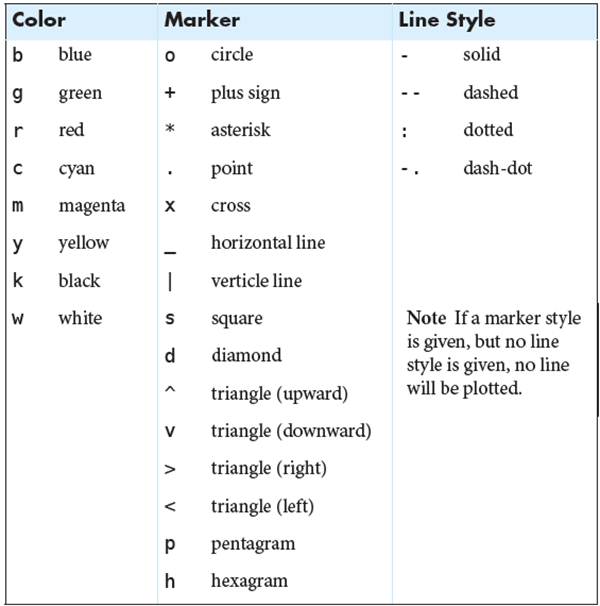

The characters can be combined in any order, let’s look at an exampling using these.

Let’s add a point marker and a solid line to our Mexico vs Year plot:

plot(Year, Mexico, ".-")

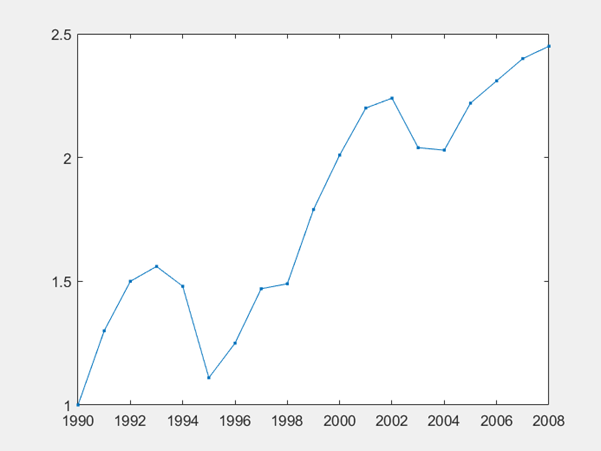

Now you try! Add a circle marker and a dashed line to your Australia vs Year plot:

%Plot data using a circle marker and a dashed line here


### **Customizing Plot Properties**

Many properties of plot elements can be specified directly using optional pairs of inputs to the plot function (and other similar plotting functions):

`plot(x,y,Property1,Value1, ...`

    `Property2,Value2,Property3,Value3,...)`

- The properties are given as text, such as "`LineWidth`".

- The accompanying value can either be a string or a numeric value, depending on the details of the property.

You can set multiple properties at once by providing multiple pairs of property names and values.

- The properties can be given in any order.

- A property must be immediately followed by its value.

- The name-value pairs appear at the end of the argument list.

Other than the properties that can be changed with line specification input (marker, line style, and line colour), the most commonly modified properties for a line plot are:

- `LineWidth` (width of the line and marker edges)

- `MarkerSize` (size of the marker symbols)

- `MarkerEdgeColor` (color of the edge of the marker symbols)

- `MarkerFaceColor` (color of the interior of the marker symbols)

Different graphical objects, including different plot types, have different sets of properties. Rather than try to remember the vast number of property names for each of the various types of graphical objects, you can access detailed documentation on [MATLAB Graphics Objects Properties](https://www.mathworks.com/help/matlab/graphics-object-properties.html).

### **Specifying Colour**

For eight specific colours, you can refer to them by name or a single letter abbreviation using the character code specified in the table under the [Plot Options](about:blank<#_Plot_Options%3E) section.

In addition to this, you can specify over ten million other colours with a 3-element vector of red-green-blue ([RGB](https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html)) values. The three elements correspond to the fractional red, green, and blue parts of the colour composition. The values in this RGB range from 0 to 1.

**Note** that you cannot use an RGB triplet in the line specification input. Instead, to specify line colour with an RGB vector, you need to provide an optional property name-value pair to the plot function. The property name is "Color" and the corresponding value is the RGB triplet.

Let’s plot the Mexico data again, this time we’ll make it red using the single letter abbreviation character code as well as the RGB vector:

%Using character code
plot(Year, Mexico, "r.-")

%Using RGB vector
plot(Year, Mexico, "Color", [1 0 0],"LineStyle", "-", "Marker", ".")

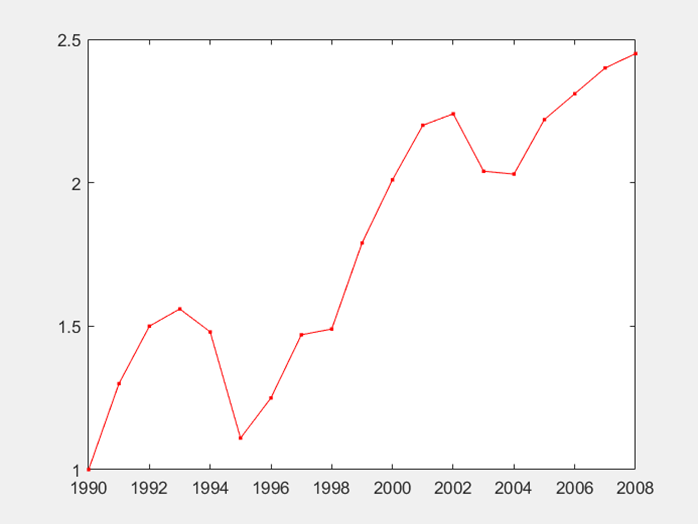

Now you try! Plot the Germany data with a solid line and an asterisk marker, the colour should be green (use both character codes and the [RGB vector](https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html)):

%Using character code


%Using RGB vector



### **Axis Control**

You can use the functions `xlim `and `ylim` to set the x- and y-axis limits. Both functions take a vector of two elements as an input.

 For example, the following command sets the lower y-axis limit for the Mexico data to 1 and the upper y-axis limit to 2.45:

plot(Year, Mexico, "r.-")

xlabel("Year")
ylabel( "Price [$US/gal]")
title("Annual gasoline prices – Mexico")

ylim([1 2.45])

When you change the x- and y-axis limits, the underlying data in the axes is not modified—it's all still there. Only the way the plot is displayed is changed.

If you want to change the axes limits to equal exactly the range of the data, use the command:

`axis tight`

axis tight

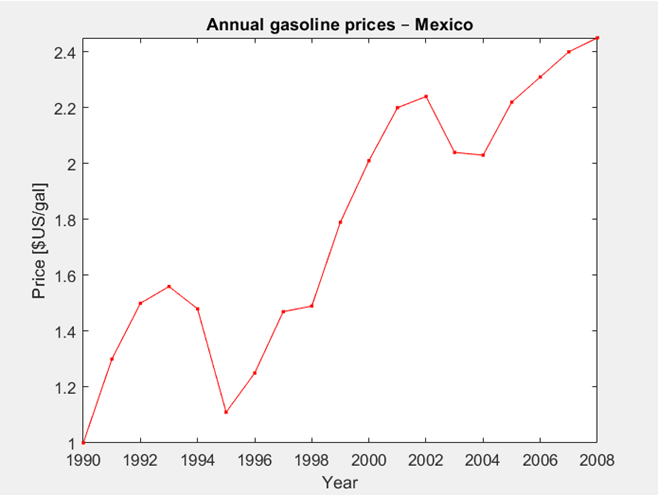

Now you try! Plot the Australia data again and change the axes limits to equal exactly the range of the data:

%Plot Australia data here


%Command that changes axes limits to equal exactly the range of the data



### **Plotting Multiple Columns**

#### **Plotting Matrix Columns**

Two-dimensional plotting functions (plot, bar, stem, etc.) behave in the same manner as statistical functions when dealing with matrices: the columns are assumed to be independent variables and plotted as separate lines.

You can use the plot function on a matrix to plot each column as a separate line in your plot.

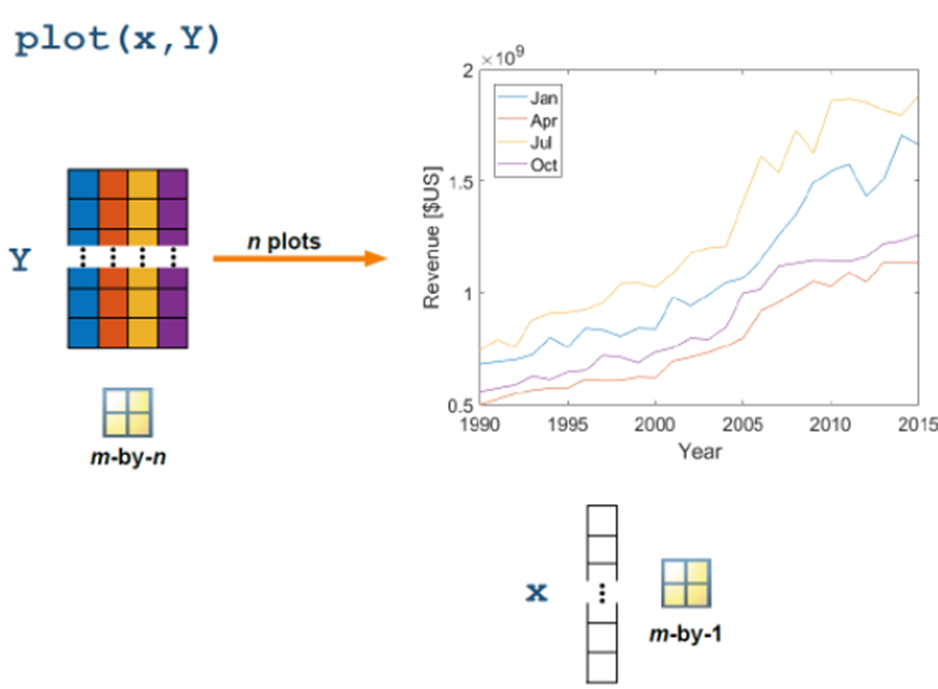

The file `electricity.mat `contains two 12-by-30 matrices, `usage `and `price`, that represent the amount of residential electricity (in MWh) sold in the U.S. and the retail price (in ¢) of a kWh of residential electricity, respectively. The 12 rows represent the 12 months of the year, and the 30 columns represent the 30 years from 1990 to 2019:

%Load the mat file
load electricity

price = price*1000/100; %Convert prices from ¢/kWh to $/MWh.

Let’s plot each year’s electricity usage simultaneously as a function of month:

plot(mth, usage)

xticks(1:12)

xticklabels(M)

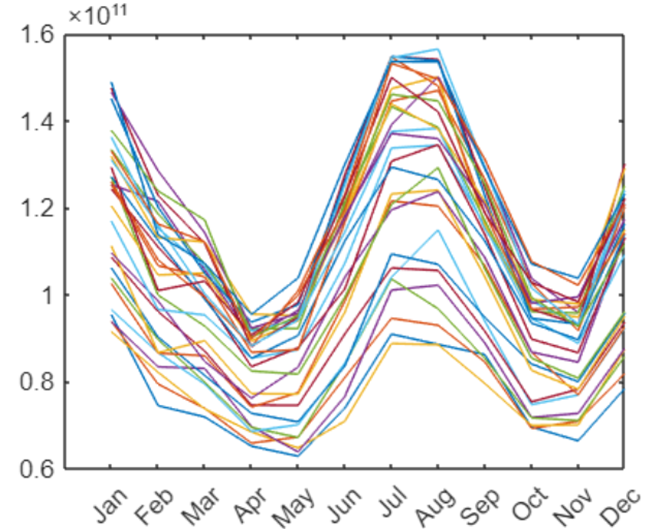

Now you try! Plot each month’s electricity usage simultaneously as a function of year (Hint: [Transpose](https://www.mathworks.com/help/matlab/ref/ctranspose.html#buaudse-6) the usage matrix):

%Plot here



Does your plot look like this?

#### **Visualizing Matrices**

You can use the surf function to visualize an m-by-n matrix by representing each value in the matrix as the height of a surface.

`surf(A)`

Just like the plot function, the data is plotted against the index values if you don't specify independent variables. If you want to specify the x and y values, you can pass those as vector input to the surf function and other matrix visualization functions.

`surf(X, Y, matrix)`

If matrix is an m-by-n matrix, x is an n-element vector that describes the columns, and y is an m-element vector that describes the rows.

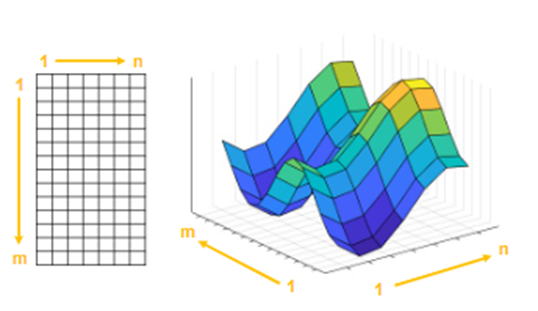

Let’s visualize the electricity revenue as a surface:

%First calculate the electricity revenue for all the years
revenue = price.*usage

surf(yr, mth, revenue) 

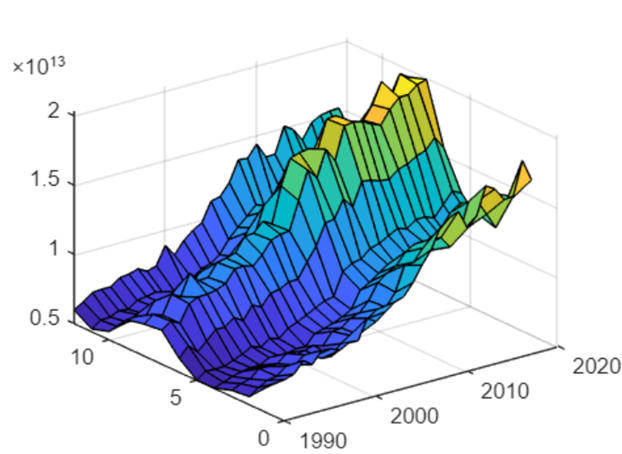

You can use the same syntax with the [**mesh**](https://www.mathworks.com/help/matlab/ref/mesh.html) function.

`mesh(X, Y, matrix)`

You can use a [**contour**](https://www.mathworks.com/help/matlab/ref/contour.html) plot to visualize matrix data in two dimensions.

`contour(X, Y, matrix)`

## Extra Learning

###  **Customized Annotations Creating Arrays of Strings**

Arrays of strings are useful for annotating visualizations. Use square brackets, [], with spaces and semicolons (;), to create a string array the same way you create a numeric matrix.

x = ["hello" "sweet";"peaceful" "world"]

`x =`

            `2`**×**`2 string array`

            `"hello"`      `"sweet"`

            `"peaceful"``   "world"`

### **Annotating Plots**

Textual information can be added to plots using separate annotation functions: `title`, `subtitle`, `xlabel`, and `ylabel`. All functions take text as input. Previously we added these annotations interactively, now we can add these to a plot programmatically. Let’s look at an example illustrating this.

Let’s label our Mexico vs Year plot, the x- and y-axis as well as the title:

plot(Year, Mexico, ".-")

xlabel("Year")
ylabel( "Price [$US/gal]")
title("Annual gasoline prices – Mexico")

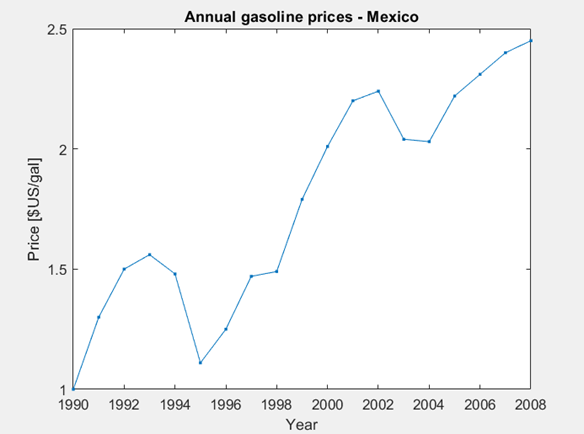

Now you try! Label the x- and y-axis as well as the title of your Australia vs Year plot:

plot(Year, Australia, "o--")

%Label your plot here




MATLAB text annotation functions use basic TeX markup interpretation. Hence, `"x^2"` becomes and `"x_2"` becomes. Use a slash (\) to display a Greek symbol in the label:

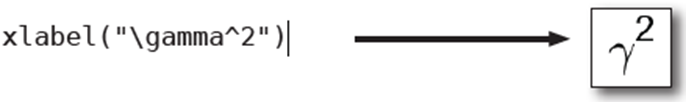

Curly braces ({}) are used as delimiters in TeX:

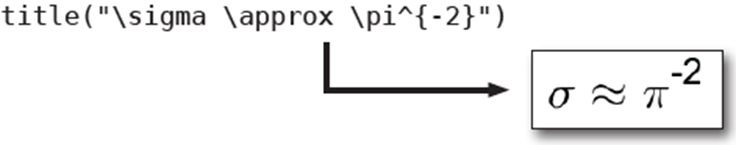

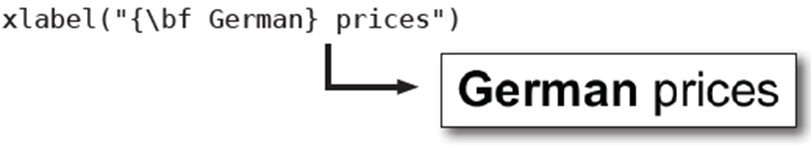

You can also display variables in labels by using them to create the string label. To add a numeric variable to a string, use the `+` operator.

Let’s add a subtitle to our Mexico plot:

plot(Year, Mexico, ".-")

xlabel("Year")
ylabel( "Price [$US/gal]")
title("Annual gasoline prices – Mexico")

subtitleText = "From " + Year(1) + " to " + Year(end);

subtitle(subtitleText)

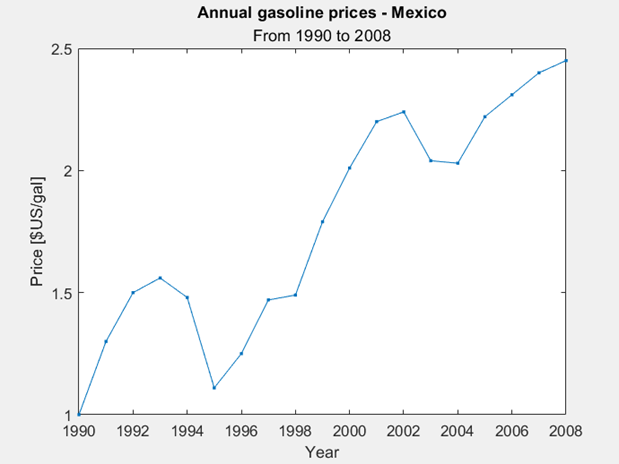

### **Adding Plots**

By default, each plot command displays its own figure output. To change this behaviour, so that you can plot multiple plots on the same axes, you can issue the hold command: 

`hold on `

All subsequent plots will be added to the current axes until the command 

`hold off` 

is issued.

Let’s plot the Mexico and Australia data on one axis:

plot(Year, Mexico, ".-")

hold on

plot(Year, Australia, "o--")

xlabel("Year")
ylabel("Price [$US/gal]")
title("Annual gasoline prices")

hold off

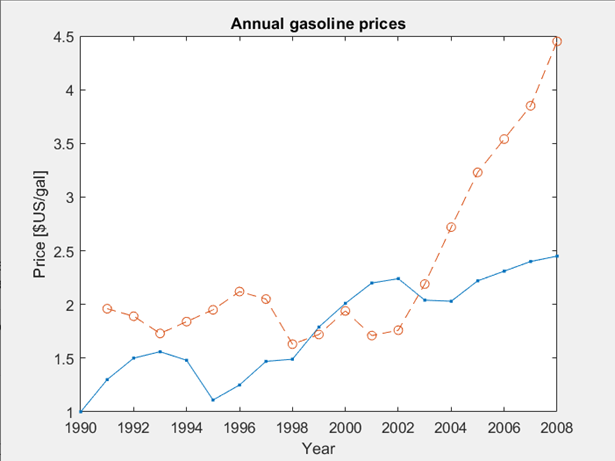

Now you try! Plot the Australia and the Germany data on one axis (the Germany plot should be a solid line with asterisk markers):

%Plot Australia data


%Command for adding additional plot on the axis


%Plot Germany data


%Label the x- and y-axis and create a title


%Last command



### **Adding Plot Legend**

You can use text inputs to the legend function to identify the components of a plot with multiple elements. Each input will be identified with each plot, in order.

`legend("Australia", "Germany", "Mexico")`

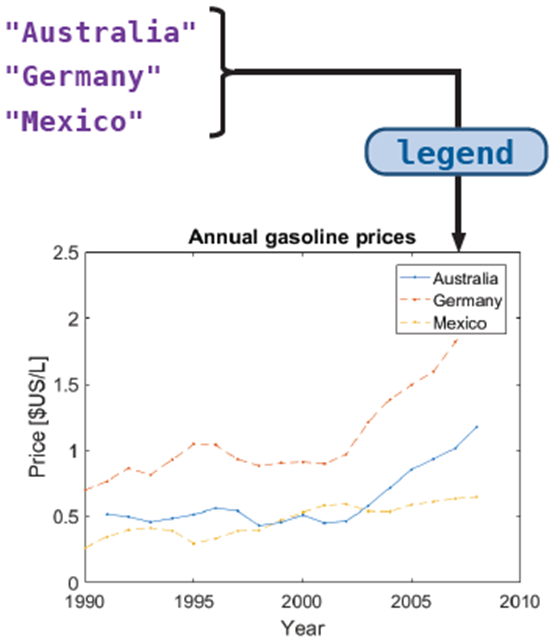

The legend function also accepts two optional arguments: the keyword "**Location**" and a text description of the location, such as "**north**" or "**southeast**":

`legend("Australia", "Germany", "Mexico",... "Location", "northwest")`

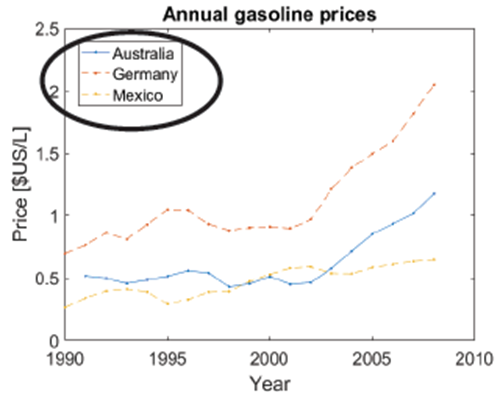

Now that we have two plots on one axis, we need to be able to identify which plot belongs to which set of data. We’re going to use the legend function to do this:

%Because we plotted Mexico first, that has to be our first input to the legend %function
plot(Year, Mexico, ".-")

hold on

plot(Year, Australia, "o--")

xlabel("Year")
ylabel("Price [$US/gal]")
title("Annual gasoline prices")

hold off

legend("Mexico", "Australia", "Location", "northwest")

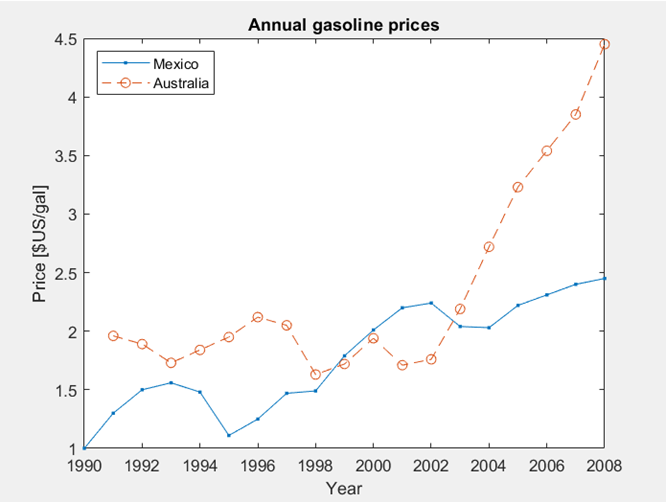

Now you try! Add a legend to your axis:

%Paste your previous code here


%Create a legend for your plot here


## What we've covered this week in Part 2

This week in Part 2 we learnt about:

- Programmatic plotting

- Plot options

- Customizing plot properties

- Specifying colour

- Axis control

- Plotting multiple columns

## **PowerPoint Presentation**

- [Week_5_Part_2_Functions_and_Graphing.pptx](matlab:open('..\PowerPoint Presentations\Week_5_Part_2_Functions_and_Graphing.pptx'))